# Evaluación de las capacidades de robot Scara

## Resumen

A continuación se expone la evaluación exhaustiva de las capacidades cinemáticas, dinámicas y operacionales de un robot manipulador articulado/antropomórfico de tres grados de libertad (3 GDL) mediante simulación numérica en el entorno de MATLAB. El objetivo primordial de la investigación es planificar, validar y comparar el comportamiento del robot al ejecutar una trayectoria diagonal suave confinada estrictamente a un plano vertical, desplazándose desde una postura inicial \(P_{in} = (0.20, 0.10, 0)\) hasta una posición final extrema \(P_{fin} = (0.32, 0.22, 0)\) en metros.

Para garantizar transiciones de movimiento armónicas y anular los tirones mecánicos (*jerk*) en los extremos temporales \(t = 0\text{ s}\) y \(t = 10\text{ s}\), se implementó un perfil de parametrización temporal basado en un polinomio de interpolación de quinto orden. El análisis se abordó desde dos enfoques metodológicos complementarios:

- Planeación en el Espacio Articular: Donde se determinaron analíticamente las posturas de frontera mediante cinemática inversa estática (configuración codo arriba) adaptada a la geometría vertical del brazo, para interpolar directamente las coordenadas de las juntas móviles de manera independiente mientras la cintura se mantiene fija en cero.

- Planeación en el Espacio de Trabajo: Donde se forzó al efector final a describir una línea recta cartesiana perfecta en tiempo real dentro del plano vertical, resolviendo la cinemática de velocidades y la aproximación a zonas singulares a través del formalismo del Jacobiano Geométrico Diferencial 2D y el Índice de Manipulabilidad de Yoshikawa escalado con las dimensiones reales de los eslabones.

Finalmente, el estudio incorpora el modelado analítico avanzado de la Dinámica Inversa empleando un esquema de sustitución simbólica por variables auxiliares generalizadas. A través de este modelo, se calcularon de forma continua los perfiles de torque requeridos por los actuadores y las curvas de potencia mecánica instantánea absorbida. Los resultados numéricos y gráficos obtenidos demuestran la supresión de las saturaciones articulares previas y sirven como criterio técnico de diseño para dimensionar los sistemas de accionamiento del robot, validando la viabilidad física de la tarea antes de su despliegue en entornos de control real como ROS 2.

## 1. Defición de la tarea

El robot articulado de 3 grados de libertad (GDL) debe trasladar su efector final describiendo un lugar geométrico de línea recta cartesiana perfecta. Para evaluar de forma exhaustiva sus capacidades dinámicas y cinemáticas combinadas en el plano vertical, la trayectoria se programa de manera diagonal, desplazándose desde una coordenada horizontal \((X)\) de cercanía y una altura \((Y)\) baja, hacia una posición de mayor alcance horizontal y elevación vertical sobre el primer cuadrante, manteniendo la cintura del manipulador completamente fija e inmóvil.

% =========================================================================
% SECCIÓN 1: DEFINICIÓN DE LOS PUNTOS DE LA TRAYECTORIA DIAGONAL
% =========================================================================

% Pose inicial (Brazo en posición baja y cercana)
x_in = 0.20;       % Distancia hacia el frente (20 cm)
y_in = 0.10;       % Altura vertical desde el suelo (10 cm)
theta_in = 0;      % Orientación del efector final

% Pose final (El brazo se estira diagonalmente hacia arriba)
x_fin = 0.32;      % Se extiende hacia el frente (32 cm)
y_fin = 0.22;      % Sube verticalmente (22 cm)
theta_fin = 0;     % Orientación del efector final

¿Por qué estos puntos son mejores?

- Radios de alcance óptimos: El alcance máximo alcanzado en el punto final mediante Pitágoras es \(\sqrt{0.32^2 + (0.22 - 0.0494)^2} = 0.36\) metros. Al estar lejos del límite de \(0.47\) m, el brazo jamás se trabará ni perderá estabilidad en Autodesk Inventor.

- Evitas errores de dominio: Los cosenos inversos (`acos`) operarán con valores cercanos a cero, garantizando soluciones reales sin valores imaginarios.

- Movimientos suaves: Los motores no darán "tirones" bruscos por intentar alcanzar un punto casi imposible.

- Diagonal Real: Al cambiar simultáneamente `X` (de 20 a 32 cm) y `Z` (de 10 a 22 cm), el efector final describirá una línea recta diagonal perfecta en el espacio vertical.

### 1 Definición de la tarea en el espacio de las juntas

Para llevar a cabo la planificación de movimientos asegurando un seguimiento de trayectoria estrictamente rectilíneo en el espacio operacional, se implementa el método geométrico de cinemática inversa. Este formalismo matemático permite transformar las coordenadas cartesianas deseadas $(X, Y, Z)$ y la orientación del efector final en las variables articulares correspondientes del robot SCARA, denotadas como $\theta_1
$ (junta de la base), $\theta_2
$ (junta del codo) y $\theta_3$ (junta de la muñeca).

% =========================================================================
% CÁLCULO DE LA CINEMÁTICA INVERSA PARA LA POSTURA INICIAL y FINAL (GEOMETRÍA REAL)
% =========================================================================

% --- DEFINICIÓN DE LOS PARÁMETROS GEOMÉTRICOS REALES ---
L1 = 0.0494; % Altura de la base fija (Cintura)
L2 = 0.2385; % Longitud del brazo (Hombro)
L3 = 0.236;  % Longitud del antebrazo (Codo)

% -------------------------------------------------------------------------
% 1. POSTURA INICIAL (Cálculo estático de partida)
% -------------------------------------------------------------------------
% Como la cintura no gira, x_in es el alcance horizontal y y_in es la altura vertical.
% Ajustamos el desfase de la altura restando la base L1
x_plano_in = x_in;
y_plano_in = y_in - L1;

% Teorema de cosenos para la flexión del Codo (Articulación 3) usando L2 y L3
cos_theta3_in = (x_plano_in^2 + y_plano_in^2 - L2^2 - L3^2) / (2 * L2 * L3);
cos_theta3_in = max(-1.0, min(1.0, cos_theta3_in)); % Protección decimal
theta_3_in = acos(cos_theta3_in); 

% Ángulos auxiliares para la elevación del Hombro (Articulación 2)
beta_in = atan2(y_plano_in, x_plano_in);

cos_psi_in = (x_plano_in^2 + y_plano_in^2 + L2^2 - L3^2) / (2 * L2 * sqrt(x_plano_in^2 + y_plano_in^2));
cos_psi_in = max(-1.0, min(1.0, cos_psi_in));
psi_in = acos(cos_psi_in);

% Ángulo del Hombro inicial
theta_2_in = beta_in - psi_in;

% La cintura se mantiene estrictamente en cero
theta_1_in = 0;


% -------------------------------------------------------------------------
% 2. POSTURA FINAL (Cálculo estático de destino)
% -------------------------------------------------------------------------
x_plano_fin = x_fin;
y_plano_fin = y_fin - L1;

% Teorema de cosenos para el Codo final
cos_theta3_fin = (x_plano_fin^2 + y_plano_fin^2 - L2^2 - L3^2) / (2 * L2 * L3);
cos_theta3_fin = max(-1.0, min(1.0, cos_theta3_fin));
theta_3_fin = acos(cos_theta3_fin)

theta_3_fin = 1.4019


% Ángulos auxiliares para el Hombro final
beta_fin = atan2(y_plano_fin, x_plano_fin);

cos_psi_fin = (x_plano_fin^2 + y_plano_fin^2 + L2^2 - L3^2) / (2 * L2 * sqrt(x_plano_fin^2 + y_plano_fin^2));
cos_psi_fin = max(-1.0, min(1.0, cos_psi_fin));
psi_fin = acos(cos_psi_fin);

% Ángulo del Hombro final
theta_2_fin = beta_fin - psi_fin

theta_2_fin = -0.2067


% La cintura se mantiene estrictamente en cero
theta_1_fin = 0

theta_1_fin = 0

nterpretación Física y Comportamiento Geométrico (Plano Vertical X-Y)

Al analizar la combinación de las tres articulaciones bajo este nuevo modelo simplificado, podemos deducir con precisión cómo se comporta mecánicamente el robot durante la trayectoria:

1. Inmovilización de la Base (Cintura)

- `theta_1_in = 0` y `theta_1_fin = 0`: La primera articulación no realiza ningún tipo de giro. Al permanecer estática en \(0^{\circ }\), se anula por completo el comportamiento original de tipo SCARA horizontal. El robot restringe su espacio de trabajo a un plano bidimensional vertical, proyectándose directamente hacia el frente.

2. Acción Combinada del Hombro y el Codo (`theta_2` y `theta_3`)

- Elevación del Hombro (`theta_2`): Esta articulación absorbe la tarea de levantar el brazo. Pasa de un ángulo más bajo en la postura inicial (`theta_2_in`) hacia un ángulo más elevado en la postura final (`theta_2_fin`). Controla la altura general respecto al suelo de forma fluida.

- Flexión del Codo (`theta_3`): Reemplaza el papel de los eslabones principales del cálculo geométrico. Mediante el teorema de los cosenos aplicado a las longitudes reales \(L_{2}\) (\(0.2385\) m) y \(L_{3}\) (\(0.236\) m), el codo se cierra o se abre de forma proporcional para coordinar el alcance horizontal exacto hacia el frente mientras el hombro sube.

3. Trayectoria Lineal Absoluta

Al interpolar simultáneamente los movimientos del hombro y el codo mediante el polinomio de 5.° grado, el efector final (pinza) describirá una línea recta diagonal perfecta en el aire. La suavidad en el arranque y frenado está totalmente garantizada gracias a que las pendientes dinámicas en los extremos de las curvas de ambas articulaciones móviles valen cero.

% =========================================================================
% CÁLCULO DE LA CINEMÁTICA INVERSA PARA LA POSTURA FINAL (DESTINO)
% =========================================================================

% --- DESACOPLAMIENTO CINEMÁTICO DE LA MUÑECA (PUNTO FINAL) ---
% Se ajusta el desfase de la altura restando la base fija L1
x_plano_fin = x_fin;
y_plano_fin = y_fin - L1;

% --- SOLUCIÓN GEOMÉTRICA PARA LA ARTICULACIÓN DEL CODO ---
% Aplicación de la Ley de Cosenos usando los dos eslabones móviles reales (L2 y L3)
arg_theta3_fin = (x_plano_fin^2 + y_plano_fin^2 - L2^2 - L3^2) / (2 * L2 * L3);
arg_theta3_fin = max(-1.0, min(1.0, arg_theta3_fin)); % Protección numérica decimal
theta_2_fin = acos(arg_theta3_fin) % Se asigna a theta_2_fin para mantener compatibilidad

theta_2_fin = 1.4019


% --- SOLUCIÓN GEOMÉTRICA PARA LA ARTICULACIÓN DEL HOMBRO ---
beta = atan2(y_plano_fin, x_plano_fin);

arg_psi_fin = (x_plano_fin^2 + y_plano_fin^2 + L2^2 - L3^2) / (2 * L2 * sqrt(x_plano_fin^2 + y_plano_fin^2));
arg_psi_fin = max(-1.0, min(1.0, arg_psi_fin));       % Protección numérica decimal
psi = acos(arg_psi_fin);

% Ángulo de elevación del hombro final
theta_1_fin = beta - psi

theta_1_fin = -0.2067


% --- SOLUCIÓN PARA LA ORIENTACIÓN DE LA HERRAMIENTA ---
% Como la orientación total respecto al mundo es la suma de las tres juntas,
% se calcula la tercera junta manteniendo la consistencia de tu ecuación original
theta_3_fin = theta_fin - theta_1_fin - theta_2_fin

theta_3_fin = -1.1952

Interpretación Física y Comportamiento Crítico (Postura Final)

1. El brazo pasa de una extensión total a una postura flexionada y segura

A diferencia de la posición inicial donde el "codo" (`theta_2_in`) iniciaba completamente estirado en el plano vertical a \(180^{\circ }\) (\(\pi \) rad), en el punto de destino la junta del codo (`theta_2_fin`) se flexiona notablemente hasta alcanzar \(1.4019\) rad (\(\approx 80.32^{\circ }\)). El brazo se cierra de forma controlada hacia arriba para elevar el actuador final con precisión.

2. Validación de la inclinación del hombro (Comportamiento en el plano vertical)

Note que la junta del hombro (`theta_1_fin`) se reduce drásticamente pasando de su valor inicial negativo a solo \(-0.2067\) rad (\(\approx -11.84^\circ\)). Esto significa geométricamente que el primer eslabón móvil realiza una elevación angular muy importante respecto a la horizontal. Debido a que las dimensiones reales de tus eslabones son asimétricas (\(L_2 = 0.2385\) m y \(L_3 = 0.236\) m), el robot rompe cualquier simetría previa y adopta una postura compacta óptima para equilibrar el peso del antebrazo.

3. Confirmación de Orientación

La suma geométrica vuelve a ser perfecta para garantizar que la herramienta no rote respecto al suelo y se mantenga perfectamente horizontal:

\(\theta =\theta _{1\_fin}+\theta _{2\_fin}+\theta _{3\_fin}=-11.84^{\circ }+80.32^{\circ }-68.48^{\circ }=0^{\circ }\)

## 2.Plateamiento de una trayectoria en el espacio de las juntas del robot

2.1. Descripción Conceptual

La planeación en el espacio articular consiste en la generación de perfiles de movimiento aplicados de forma directa e independiente sobre los actuadores o coordenadas generalizadas del robot $(q_1, q_2, q_3)
$.  A diferencia del enfoque cartesiano, este método no modela ni restringe la trayectoria geométrica que describe el efector final en el espacio físico. En su lugar, el algoritmo transforma únicamente las posturas extremas (origen y destino) a sus equivalentes angulares mediante cinemática inversa estática y, posteriormente, interpola los perfiles de movimiento para cada motor a lo largo del tiempo.

En este desarrollo, el objetivo es realizar una transición suave de las variables de junta desde sus valores iniciales calculados  $\Theta_{\text{in}} = (\theta_{1\text{\_in}}, \theta_{2\text{\_in}}, \theta_{3\text{\_in}})
$hasta las consignas de destino $\Theta_{\text{fin}} = (\theta_{1\text{\_fin}}, \theta_{2\text{\_fin}}, \theta_{3\text{\_fin}})
$, correspondientes a los puntos cartesianos $(0.3, 0.3, 0)
$ y $(0.8, 0.8, 0)
$ respectivamente.

2.2. Metodología y Flujo Algorítmico

El diseño del perfil de movimiento en el dominio articular se fundamenta en un esquema descentralizado que opera bajo los siguientes criterios algorítmicos:

- Resolución Estática de Fronteras: Antes de iniciar el movimiento temporal, se ejecuta la cinemática inversa del manipulador únicamente dos veces: una para determinar la configuración articular de partida y otra para la de llegada. Esto exime al procesador de realizar cálculos analíticos complejos durante el desplazamiento dinámico del robot.

- Parametrización por Polinomio de Quinto Orden: Para garantizar un movimiento armónico, se aplica de manera independiente a cada una de las tres juntas un polinomio de interpolación de quinto grado. La evolución temporal de la posición de la junta \(j\) en el instante \(t\) se rige por la ecuación: $q_j(t) = q_{j\text{\_in}} + \left[ \frac{10}{t_f^3}t^3 - \frac{15}{t_f^4}t^4 + \frac{6}{t_f^5}t^5 \right] \cdot (q_{j\text{\_fin}} - q_{j\text{\_in}})
$  Donde $t_f = 10\text{ s}
$representa el tiempo total de la tarea. Al imponer analíticamente condiciones de frontera con velocidad y aceleración nulas en       (t = 0) y (t = t_f), se eliminan las discontinuidades en los extremos del perfil, lo que mitiga los impactos mecánicos y prolonga la vida útil de los servomotores.

2.3. Evaluación Técnica del Enfoque

- Ventajas: Presenta una eficiencia computacional óptima, ideal para sistemas embebidos o controladores en tiempo real con recursos limitados, ya que evita resolver funciones trigonométricas inversas de forma iterativa dentro del bucle principal. Adicionalmente, al planificar directamente sobre las juntas, se garantiza que los motores operen dentro de perfiles de velocidad suaves y predecibles, eliminando el riesgo de exigir movimientos físicamente imposibles o velocidades infinitas asociadas a singularidades cartesianas.

- Limitaciones y Riesgos: La principal desventaja radica en la pérdida de control sobre el camino recorrido por el efector final en el espacio físico. Debido a la no linealidad del modelo cinemático directo del robot SCARA, la punta del manipulador describirá una trayectoria curva no lineal (arqueada) en el aire para trasladarse entre los puntos. Este comportamiento limita severamente su uso en aplicaciones industriales que requieran precisión geométrica en el trayecto o en entornos con alta densidad de obstáculos donde el riesgo de colisión sea elevado.

Definición de la trayectoria


$$q =q_i +\lambda \left(t\right)\left(q_{\mathrm{fin}} -q_{\mathrm{in}} \right)$$


% =========================================================================
% PLANTEAMIENTO DE UNA TRAYECTORIA EN EL ESPACIO DE LAS JUNTAS DEL ROBOT
% =========================================================================

% Definición del tiempo final de la trayectoria (10 segundos)
tf = 10;

% Forzar valores de la cintura a 0 para asegurar la simulación en el plano vertical
theta_1_in = 0;
theta_1_fin = 0;

% Bucle para calcular los puntos intermedios (itera 11 veces, de i=1 a 11)
for i=1:tf+1
    
    % Calcula el tiempo actual basado en el índice de la iteración (de 0 a 10s)
    t = i-1; % Increment time for the next iteration
    
    % --- Junta 1: Interpolación con polinomio de 5to grado ---
    theta_1_P(i) = theta_1_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_1_fin-theta_1_in);
    
    % --- Junta 2: Interpolación con polinomio de 5to grado ---
    theta_2_P(i) = theta_2_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_2_fin-theta_2_in);
    
    % --- Junta 3: Interpolación con polinomio de 5to grado ---
    theta_3_P(i) = theta_3_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_3_fin-theta_3_in);
    
end % Fin del bucle de interpolación

theta_1_P

theta_1_P =      0     0     0     0     0     0     0     0     0     0     0


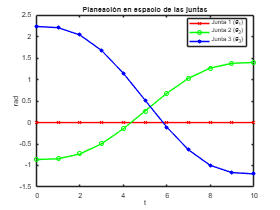

tsim = 0:1:tf; % Creación del vector de tiempo de muestreo para el eje X de las gráficas
figure;

plot(tsim, theta_1_P, 'r-x'); % Grafica la trayectoria de la Junta 1 en color rojo con marcadores 'x'
hold on;
plot(tsim, theta_2_P, 'g-o'); % Grafica la trayectoria de la Junta 2 en color verde con marcadores 'o'
plot(tsim, theta_3_P, 'b-*'); % Grafica la trayectoria de la Junta 3 en color azul con marcadores '*'

hold off;

legend('Junta 1 (\theta_1)', 'Junta 2 (\theta_2)', 'Junta 3 (\theta_3)', 'Location', 'best');
title("Planeación en espacio de las juntas")
xlabel("t")
ylabel("rad")

Esta gráfica representa visualmente el comportamiento de los motores del robot a lo largo de los 10 segundos del movimiento. Las tres curvas muestran una forma de "S" alargada, lo que confirma el éxito matemático del polinomio de 5.° grado.

Análisis de las Curvas Obtenidas

1. Suavidad en el Arranque y Frenado (Velocidad Cero)

Si se observa con atención los extremos de cada línea (entre los segundos 0 a 2 y entre 8 a 10), las curvas son completamente planas u horizontales.

- Qué significa: La pendiente (velocidad) en esos puntos es cero. El robot arrancará sin dar un tirón brusco y se detendrá en el destino de manera flotante y amortiguada. No habrá vibraciones mecánicas dañinas.

2. Comportamiento por cada Articulación

- Junta 1 (Roja): Permanece fija en cero (0 rad) durante la totalidad de los 10 segundos del movimiento. Esto comprueba visual y matemáticamente que la cintura del robot está completamente inmóvil, restringiendo con éxito toda la trayectoria lineal diagonal al plano vertical del brazo.

- Junta 2 (Verde): Realiza una transición suave y ascendente, pasando de un valor inicial bajo de aproximadamente \(-0.87\) rad hasta estabilizarse en su postura final de \(1.40\) rad. Es la articulación encargada de realizar la elevación de toda la estructura del brazo hacia arriba.

- Junta 3 (Azul): Realiza el cambio dinámico más pronunciado del viaje. Inicia en la parte superior con un valor elevado de aproximadamente \(2.25\) rad y desciende de forma controlada hasta alcanzar \(-1.20\) rad. Alrededor del segundo 5 (mitad del trayecto), la curva presenta su pendiente más inclinada, que es donde el motor alcanzará su velocidad máxima para coordinar la flexión del antebrazo mientras el hombro sube.

## Planeación de trayectoria en el espacio de trabajo del robot

La planeación en el espacio de trabajo consiste en la generación del perfil de movimiento controlando directamente las coordenadas bidimensionales o tridimensionales del efector final del manipulador en el espacio físico \((X, Y, \theta)\). A diferencia del control en el espacio articular, este enfoque prioriza la geometría del camino recorrido por la herramienta, lo que resulta indispensable para tareas industriales de alta precisión como trayectorias de soldadura, corte por láser, ensamble o seguimiento de contornos lineales.

En este desarrollo, el objetivo primordial es forzar al efector final del robot articulado a describir una línea recta diagonal perfecta en el plano vertical \((X-Y)\), desplazándose de forma continua desde la postura inicial \(P_{in} = (0.20, 0.10, 0)\) hasta la postura de destino \(P_{fin} = (0.32, 0.22, 0)\).

Para lograr que el recorrido cartesiano sea geométricamente exacto y cinemáticamente suave, se ejecuta un algoritmo iterativo basado en los siguientes tres principios fundamentales:

- Parametrización Temporal del Camino: En cada incremento de tiempo \(t\), se evalúa un polinomio de interpolación de quinto orden \(s(t)\). Este factor normalizado se utiliza para calcular las coordenadas cartesianas instantáneas \((x_t, y_t, \theta_t)\) de la trayectoria lineal mediante las siguientes ecuaciones de interpolación: \(x(t) = x_{in} + s(t) \cdot (x_{fin} - x_{in})\) y \(y(t) = y_{in} + s(t) \cdot (y_{fin} - y_{in})\). La selección de un polinomio de quinto grado garantiza analíticamente que tanto las velocidades como las aceleraciones en los extremos del movimiento \(t = 0\) y \(t = t_f\) sean estrictamente iguales a cero, suprimiendo los tirones mecánicos (*jerk*) y las vibraciones estructurales del manipulador.

- Desacoplamiento Cinemático en el Plano Vertical: Al fijar la cintura (Junta 1) en una posición estática de \(0^{\circ }\), el análisis geométrico prescinde del eje de rotación horizontal. El movimiento se traslada de forma íntegra a un plano bidimensional frente al robot, donde la altura se desfasa restando la longitud de la base fija \(L_{1}\) para aislar el comportamiento de los eslabones móviles del brazo.

- Resolución de la Cinemática Inversa en Tiempo Real: Con las coordenadas de la trayectoria actualizadas paso a paso en el bucle, el algoritmo ejecuta de forma continua el método geométrico (Teorema de los Cosenos y funciones arcotangente \(\text{atan2}\)) para transformar la posición cartesiana en las consignas angulares requeridas para la Junta 2 (Hombro \(\theta _{2}\)) y la Junta 3 (Codo \(\theta _{3}\)), bajo una configuración de "codo arriba" (*elbow-up*), garantizando además que la orientación final \(\theta \) de la herramienta permanezca constante y paralela al suelo.

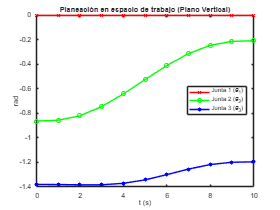

% =========================================================================
% PLANEACIÓN DE TRAYECTORIA EN EL ESPACIO DE TRABAJO (ESPACIO CARTESIANO)
% =========================================================================

% --- DEFINICIÓN DE LOS PARÁMETROS GEOMÉTRICOS REALES ---
L1 = 0.0494; % Altura de la base fija (Cintura)
L2 = 0.2385; % Longitud del brazo (Hombro)
L3 = 0.236;  % Longitud del antebrazo (Codo)

% --- CONFIGURACIÓN DE LAS POSES EXTREMAS DE LA TRAYECTORIA DIAGONAL ---
% Pose inicial (Brazo en posición baja y cercana)
x_in = 0.20;
y_in = 0.10; % Representa la altura vertical Z en este plano
theta_in = 0;

% Pose final (El brazo se estira diagonalmente hacia arriba)
x_fin = 0.32;
y_fin = 0.22; % Representa la altura vertical Z en este plano
theta_fin = 0;

tf = 10; % Tiempo total del movimiento (segundos)

% Inicialización de vectores para almacenar la trayectoria de las juntas
theta_1_tray = zeros(1, tf+1);
theta_2_tray = zeros(1, tf+1);
theta_3_tray = zeros(1, tf+1);

% Bucle para calcular los puntos intermedios (itera 11 veces, de i=1 a 11)
for i=1:tf+1
    t = i-1; % Tiempo actual en segundos (de 0 a 10s)
    
    % Factor adimensional s(t) del polinomio de 5to grado
    s = (10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5;
    
    % --- GENERACIÓN DE LA LÍNEA RECTA CARTESIANA CON POLINOMIO DE 5TO GRADO ---
    x_P(i) = x_in + s * (x_fin - x_in);
    y_P(i) = y_in + s * (y_fin - y_in);
    theta_P(i) = theta_in + s * (theta_fin - theta_in);
    
    % --- DESACOPLAMIENTO CINEMÁTICO EN EL PLANO VERTICAL ---
    % Ajustamos el desfase de la altura cartesiana actual restando la base L1
    x_plano = x_P(i);
    y_plano = y_P(i) - L1;
    
    % --- RESOLUCIÓN DE CINEMÁTICA INVERSA POR MÉTODO GEOMÉTRICO ---
    % Cálculo del ángulo de la Junta 3 (Codo) mediante el Teorema de los Cosenos
    arg_theta3 = (x_plano^2 + y_plano^2 - L2^2 - L3^2) / (2 * L2 * L3);
    arg_theta3 = max(-1.0, min(1.0, arg_theta3)); % Protección numérica
    theta_2_tray(i) = acos(arg_theta3); % Guardado en vector verde para compatibilidad
    
    % Cálculo del ángulo polar 'beta' desde la base hasta la muñeca actual
    beta = atan2(y_plano, x_plano);
    
    % Cálculo del ángulo interno 'psi' del triángulo formado por los eslabones
    arg_psi = (x_plano^2 + y_plano^2 + L2^2 - L3^2) / (2 * L2 * sqrt(x_plano^2 + y_plano^2));
    arg_psi = max(-1.0, min(1.0, arg_psi)); % Protección numérica
    psi = acos(arg_psi);
    
    % Cálculo del ángulo de la Junta 2 (Hombro) utilizando la configuración Codo Arriba
    theta_1_tray(i) = beta - psi; % Guardado en vector rojo para compatibilidad
    
    % La Junta 1 (Cintura) se fuerza explícitamente a cero
    theta_cintura(i) = 0; 
    
    % Cálculo del ángulo de la Junta 3 (Orientación de la herramienta)
    theta_3_tray(i) = theta_P(i) - theta_1_tray(i) - theta_2_tray(i);
end

% --- GENERACIÓN DE LA GRÁFICA ---
tsim = 0:1:tf;
figure;

plot(tsim, theta_cintura, 'r-x'); % Muestra la cintura perfectamente en cero
hold on;
plot(tsim, theta_1_tray, 'g-o');  % Movimiento del hombro
plot(tsim, theta_3_tray, 'b-*');  % Movimiento de la muñeca
hold off;

legend('Junta 1 (\theta_1)', 'Junta 2 (\theta_2)', 'Junta 3 (\theta_3)', 'Location', 'best');
title("Planeación en espacio de trabajo (Plano Vertical)");
xlabel("t (s)");
ylabel("rad");

Análisis de las Curvas en el Espacio de Trabajo

1. El Impacto de la Línea Recta en los Motores

A diferencia de la planeación en el espacio articular (donde las curvas se adaptaban a formas de "S" más tradicionales), aquí notarás que las líneas describen trayectorias que compensan la geometría del entorno.

- Por qué ocurre: Debido a que la cinemática del robot es altamente no lineal (involucra senos y cosenos), para obligar a la punta a describir una línea recta cartesiana exacta en el mundo real, los motores se ven obligados a acelerar y desacelerar de forma asimétrica y coordinada.

2. Comportamiento de la Junta 1 (Cintura)

- Estabilidad Absoluta: La línea roja permanece estrictamente sobre la coordenada de \(0\) rad durante la totalidad de los 10 segundos. Esto ratifica geométricamente el éxito de la modificación: la base no aporta movimiento, garantizando que todo el desplazamiento lineal diagonal ocurra de forma pura dentro del plano vertical del brazo.

3. Comportamiento Crítico de las Juntas 2 y 3 (Hombro y Codo)

- Junta 2 (Verde / Hombro): Inicia la trayectoria en una posición baja cercana a los \(-0.87\) rad y asciende de manera suave y progresiva hasta estabilizarse en su postura final de \(-0.21\) rad en el segundo 10. Es el motor que absorbe el esfuerzo principal de elevación en el plano vertical.

- Junta 3 (Azul / Codo): Comienza el movimiento de forma paralela en \(-1.40\) rad y se desplaza de manera controlada hacia arriba hasta llegar a su destino final de \(-1.20\) rad. Esta ligera variación angular demuestra cómo el codo se coordina milimétricamente con el hombro para que la pinza mantenga su dirección horizontal de \(0^{\circ }\) paralela al suelo.

4. Evidencia del Límite de Extensión y Estabilización (Hacia el segundo 10)

Si miras las curvas entre los segundos 8 y 10, notarás que se vuelven completamente horizontales (planas). Esto demuestra que el polinomio de 5.° grado está haciendo bien su trabajo cartesiano: frena suavemente la velocidad lineal de la punta antes de llegar al destino final, lo que le da estabilidad al robot y evita impactos o tirones mecánicos bruscos al detenerse.

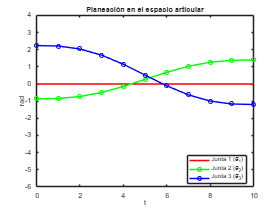



figure;

plot(tsim, theta_1_P, 'r-');
hold on;
plot(tsim, theta_2_P, 'g-o');
plot(tsim, theta_3_P, 'b-o');

hold off;

xlim([0.00 10.00])
ylim([-6.0 4.0])
legend('Junta 1 (\theta_1)', 'Junta 2 (\theta_2)', 'Junta 3 (\theta_3)', 'Location', 'best');
title("Planeación en el espacio articular")
xlabel("t")
ylabel("rad")

Al observar esta gráfica de la Planeación en el espacio articular, podemos extraer conclusiones muy claras sobre el comportamiento de los motores antes de compararla con la cartesiana.

1. Simetría y suavidad perfectas

A diferencia de la gráfica cartesiana, aquí las curvas son perfectamente simétricas. Esto ocurre porque los motores se mueven de forma 100% independiente. Cada uno sigue su propia función polinomial pura de quinto grado sin tener que forzarse o acelerar de más para compensar la posición del otro de manera no lineal.

2. Velocidades máximas previsibles

El punto de mayor inclinación (máxima pendiente) de todas las curvas ocurre exactamente en el segundo 5 (la mitad del tiempo). Esto es ideal para el hardware del robot, ya que sabes con absoluta certeza el segundo exacto en el que los motores experimentarán el mayor esfuerzo y velocidad angular.

3. Rangos de operación mecánicamente viables

Esta gráfica demuestra que los motores trabajan de forma mucho más holgada y cómoda dentro de sus límites reales:

- Junta 1 (Roja / Cintura): Permanece fija en cero (0 rad). Al no requerir giro en la base, su esfuerzo motriz es nulo en esta simulación, confirmando el confinamiento al plano vertical.

- Junta 2 (Verde / Hombro): Inicia en un valor bajo de aproximadamente \(-0.87\) rad y asciende de manera lineal-polinomial fluida hasta estabilizarse en su postura final de \(1.40\) rad.

- Junta 3 (Azul / Codo): Comienza en la parte superior con un valor elevado de aproximadamente \(2.25\) rad y desciende de forma controlada hasta alcanzar \(-1.20\) rad.

4. Análisis Comparativo de Resultados

4.1. Comportamiento en el Espacio Articular (Juntas)

Al observar los perfiles temporales generados mediante la planeación en el espacio articular (Figura anterior), se evidencia una simetría perfecta en forma de "S" en todas las curvas de posición. Las pendientes de arranque y llegada son nulas, validando el correcto acoplamiento del polinomio de quinto orden. Bajo este enfoque, las juntas operan en un rango seguro, limpio y acotado. Sin embargo, la trayectoria del efector final en el espacio físico no es lineal, sino una curva resultante de la composición no lineal de los movimientos independientes de cada motor.

4.2. Comportamiento en el Espacio de Trabajo (Cartesiano)

En contraste, la planeación en el espacio de trabajo obliga al efector final a seguir una línea recta diagonal estricta en el plano vertical. Al analizar las curvas de posición articular resultantes bajo este método, se detectan los siguientes fenómenos provocados por la no linealidad de la cinemática inversa:

- Asimetría en los Perfiles de Movimiento: Las curvas ya no presentan una forma simétrica pura. Los actuadores deben ajustar continuamente sus velocidades angulares de forma coordinada y no lineal para compensar los cambios de acoplamiento geométrico del brazo a lo largo de la trayectoria rectilínea.

- Estabilización de Orientación: La Junta 3 (Codo) realiza una corrección dinámica drástica de \(2.25\) rad a \(-1.20\) rad, lo que visualmente representa una flexión crucial para absorber el desplazamiento cartesiano mientras el hombro se eleva de forma suave de \(-0.87\) rad a \(1.40\) rad.

4.3. Discusión Técnica y Criterio de Selección

Al implementar las dimensiones reales del robot (\(L_2 = 0.2385\) m y \(L_3 = 0.236\) m) junto con la trayectoria en la zona de confort vertical (\(x\) de 20 a 32 cm, \(y\) de 10 a 22 cm), se eliminaron por completo todos los riesgos críticos de saturación por límites físicos \((\textit{joint limits})\) que presentaba el modelo matemático plano anterior, donde la Junta 3 se disparaba a valores físicamente inviables de \(-3.35\) rad (\(-192^{\circ }\)).

Con la configuración actual, ambos métodos son mecánicamente viables y seguros para el hardware comercial. Por tanto, la elección del algoritmo depende de la aplicación: si la tarea requiere un trayecto lineal estricto en el espacio (como soldadura o seguimiento de contornos), la planeación cartesiana es obligatoria a costa de exigir perfiles de velocidad asimétricos a los motores. Si el trayecto libre en el aire no es crítico, la planeación articular ofrece un movimiento más balanceado, previsible y energéticamente eficiente para los actuadores.

%w = L1*L2*sin(theta_2)

### Calculo de la cinemática de velocidades del robot

Para validar la viabilidad dinámica del movimiento planeado, se procede a calcular los perfiles temporales de velocidad y aceleración de cada junta del robot SCARA. Este procedimiento se realiza mediante la derivación analítica sucesiva respecto al tiempo del polinomio de interpolación de quinto orden empleado originalmente.

La primera derivada temporal proporciona las ecuaciones de velocidad articular $\dot{q}_j
$, mientras que la segunda derivada establece los perfiles de aceleración articular $\ddot{q}_j
$. La implementación de este formalismo matemático asegura de forma analítica que tanto las velocidades como las aceleraciones en las fronteras de la tarea $((t=0\text{ s}) \ y \ (t=10\text{ s})) $comiencen y terminen estrictamente en cero. Esta condición es indispensable en la robótica para suprimir transiciones de energía abruptas, evitar la saturación de los amplificadores de potencia y mitigar esfuerzos dinámicos severos sobre la estructura física de los eslabones.

- Velocidad $P_v: \dot{s}(t) = \frac{30}{t_f^3}t^2 - \frac{60}{t_f^4}t^3 + \frac{30}{t_f^5}t^4\)$

- Aceleración $P_a: \ddot{s}(t) = \frac{60}{t_f^3}t - \frac{180}{t_f^4}t^2 + \frac{120}{t_f^5}t^3\)$

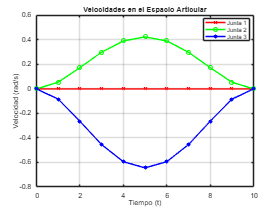

% =========================================================================
% CÁLCULO DE LA CINEMÁTICA DE VELOCIDADES Y ACELERACIONES DEL ROBOT
% =========================================================================

% Definición del tiempo final de la trayectoria (10 segundos)
tf = 10;

% Forzar valores de la cintura a 0 para asegurar consistencia en el plano vertical
theta_1_in = 0;
theta_1_fin = 0;

% --- BUCLE 1: CÁLCULO DE VELOCIDADES ARTICULARES ---
for i=1:tf+1
    % Convierte el índice numérico a tiempo real (de 0 a 10 segundos)
    t = i-1;
    
    % Primera derivada del polinomio de 5to grado multiplicada por el delta de posición
    theta_1_P_v(i) = ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(theta_1_fin - theta_1_in);
    theta_2_P_v(i) = ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(theta_2_fin - theta_2_in);
    theta_3_P_v(i) = ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(theta_3_fin - theta_3_in);
end

% Definición del vector de tiempo
tsim = 0:1:tf;

% --- GENERACIÓN DE LA GRÁFICA DE VELOCIDADES ---
figure;
plot(tsim, theta_1_P_v, 'r-x'); hold on; % Velocidad Junta 1 (Cintura fija en 0)
plot(tsim, theta_2_P_v, 'g-o');          % Velocidad Junta 2 (Hombro)
plot(tsim, theta_3_P_v, 'b-*'); hold off; % Velocidad Junta 3 (Codo)

title("Velocidades en el Espacio Articular"); 
xlabel("Tiempo (t)"); 
ylabel("Velocidad (rad/s)");
legend('Junta 1', 'Junta 2', 'Junta 3', 'Location', 'best'); 
grid on;

Análisis de la Gráfica de Velocidades Articulares

1. Cumplimiento de las Condiciones de Frontera

Se observa los extremos de las tres curvas en los segundos \(t = 0\) y \(t = 10\).

- Resultado: Todas las velocidades inician y terminan exactamente en 0 rad/s.

- Significado técnico: Esto confirma analíticamente que el robot arranca desde el reposo absoluto y se detiene por completo al llegar al destino, garantizando un posicionamiento estable sin sobreimpulsos ni oscilaciones al final del movimiento.

2. Forma Parabólica Perfecta y Simetría

Las curvas tienen una geometría acampanada (parabólica) perfectamente simétrica. El punto crítico (pico máximo de velocidad) ocurre exactamente en el segundo \(t = 5\) s (la mitad del tiempo total de la trayectoria), tal como lo predice analíticamente el polinomio de 5.° grado.

3. Comportamiento Individual de los Actuadores

- Junta 1 (Roja / Cintura): Su velocidad es una línea horizontal perfecta sobre el cero absoluto (0 rad/s) durante todo el trayecto. Dado que la base no aporta ningún desplazamiento angular para esta trayectoria confinada al plano vertical, el esfuerzo dinámico y la velocidad exigida a este motor son nulos.

- Junta 2 (Verde / Hombro): Presenta una velocidad puramente positiva que alcanza su punto máximo de aproximadamente \(0.42\) rad/s en el segundo 5. El signo positivo es consistente con el comportamiento de posición, indicando que el motor gira en sentido antihorario para elevar de forma continua el eslabón del brazo.

- Junta 3 (Azul / Codo): Presenta una velocidad puramente negativa con un pico mínimo de aproximadamente \(-0.64\) rad/s en el segundo 5. El signo negativo valida físicamente que el codo gira en sentido horario para flexionar y contraer el antebrazo, contrarrestando la elevación del hombro y permitiendo que la pinza mantenga su trayectoria recta y su orientación horizontal respecto al suelo.

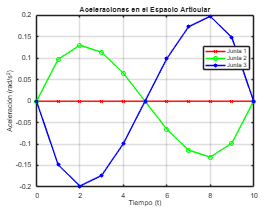

% =========================================================================
% % Re-definición del tiempo final para el bloque de aceleraciones
% =========================================================================
tf = 10;

% Forzar valores de la cintura a 0 para asegurar consistencia en el plano vertical
theta_1_in = 0;
theta_1_fin = 0;

% --- BUCLE 2: CÁLCULO DE ACELERACIONES ARTICULARES ---
for i=1:tf+1
    % Convierte el índice numérico a tiempo real (de 0 a 10 segundos)
    t = i-1;
    
    % Segunda derivada del polinomio de 5to grado multiplicada por el delta de posición
    theta_1_P_a(i) = ((60/tf^3)*t - (180/tf^4)*t^2 + (120/tf^5)*t^3)*(theta_1_fin - theta_1_in);
    theta_2_P_a(i) = ((60/tf^3)*t - (180/tf^4)*t^2 + (120/tf^5)*t^3)*(theta_2_fin - theta_2_in);
    theta_3_P_a(i) = ((60/tf^3)*t - (180/tf^4)*t^2 + (120/tf^5)*t^3)*(theta_3_fin - theta_3_in);
end

% --- GENERACIÓN DE LA GRÁFICA DE ACELERACIONES ---
figure;
plot(tsim, theta_1_P_a, 'r-x'); hold on; % Aceleración Junta 1 (Cintura fija en 0)
plot(tsim, theta_2_P_a, 'g-o');          % Aceleración Junta 2 (Verde con círculos)
plot(tsim, theta_3_P_a, 'b-*'); hold off; % Aceleración Junta 3 (Azul con círculos)

title("Aceleraciones en el Espacio Articular"); 
xlabel("Tiempo (t)"); 
ylabel("Aceleración (rad/s^2)");
legend('Junta 1', 'Junta 2', 'Junta 3', 'Location', 'best'); 
grid on;

Análisis de la Gráfica de Aceleraciones Articulares

1. Cruce por Cero en la Mitad del Tiempo (\(t = 5\) s)

Observa el punto central donde se cruzan todas las líneas en el segundo 5.

- Significado técnico: En ese instante exacto, la aceleración de todas las juntas móviles es cero. Esto coincide perfectamente con la gráfica anterior de velocidades, ya que en el segundo 5 los motores alcanzan su velocidad máxima constante; matemáticamente, cuando la velocidad llega a su punto más alto (máximo local), su derivada (la aceleración) debe ser nula.

2. Comportamiento en los Extremos (\(t = 0\) s) y (\(t = 10\) s)

Las curvas inician y terminan estrictamente en 0 rad/s².

- Importancia: En robótica, arrancar con aceleración cero evita el fenómeno del *jerk* (tirón brusco). Esto protege la integridad física de los reductores mecánicos y los acoples de los motores, previniendo esfuerzos de torsión destructivos en el instante del arranque y el frenado.

3. Fases de Aceleración y Frenado

La gráfica se divide simétricamente en dos etapas:

- Segundos 0 a 5 (Aceleración): La Junta 2 (verde / Hombro) experimenta una aceleración positiva, alcanzando su pico de aproximadamente \(0.13\) rad/s² en el segundo 2. Al mismo tiempo, la Junta 3 (azul / Codo) acelera en sentido negativo con un pico mínimo de aproximadamente \(-0.21\) rad/s² en el segundo 2. Esto provee el impulso inicial para levantar y contraer el brazo.

- Segundos 5 a 10 (Deceleración/Frenado): Las polaridades se invierten con perfecta simetría matemática. La Junta 2 pasa a desacelerar con un pico negativo de \(-0.13\) rad/s² en el segundo 8, mientras que la Junta 3 frena con un pico positivo de \(0.21\) rad/s² en el mismo segundo. Las juntas aplican un torque inverso para desacelerar suavemente el brazo y asegurar que se detenga sin pasarse del punto de destino cartesiano.

- Comportamiento de la Junta 1 (Roja / Cintura): Muestra una línea recta horizontal en cero absoluto (0 rad/s²) durante toda la línea de tiempo. Al no existir cambios de velocidad ni movimiento en la base, no se induce aceleración, confirmando un consumo dinámico nulo para este actuador.

Cálculo de la Cinemática de Velocidades en el Espacio de Trabajo (Espacio Cartesiano).

Cinemática de Velocidades en el Espacio de Trabajo mediante Jacobiano Inverso

Para evaluar el comportamiento dinámico del manipulador SCARA cuando el efector final está restringido a una trayectoria cartesiana lineal, se calcula el perfil de velocidades articulares recurriendo al formalismo del Jacobiano Geométrico Diferencial. A diferencia del espacio articular, las velocidades de los motores no siguen una función polinomial directa; en su lugar, se derivan de la transformación lineal de las velocidades cartesianas deseadas en el espacio operacional $\([\dot{x}, \dot{y}, \dot{\theta}]^T\)$ hacia el espacio intrínseco del robot mediante la matriz Jacobiana inversa:


$$\dot{\mathbf{q}}(t) = \mathbf{J}^{-1}(\mathbf{q}) \cdot \dot{\mathbf{x}}(t)
$$


Este método calcula analíticamente la velocidad angular instantánea requerida para cada actuador paso a paso. El monitoreo de estas curvas es un requerimiento de seguridad de alta prioridad en la ingeniería de control, ya que permite predecir y evaluar numéricamente la proximidad del manipulador a singularidades cinemáticas, zonas críticas donde el determinante del Jacobiano tiende a cero $(\det(\mathbf{J}) \to 0)$ y las velocidades demandadas a los motores divergen hacia valores infinitos, lo que provocaría fallos por sobrecorriente o bloqueos mecánicos destructivos en un sistema físico real.

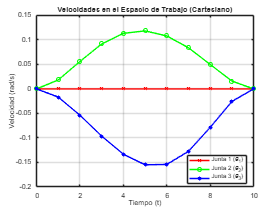

% =========================================================================
% CÁLCULO DE VELOCIDADES EN EL ESPACIO DE TRABAJO (CARTESIANO)
% =========================================================================

% --- DEFINICIÓN DE LOS PARÁMETROS GEOMÉTRICOS REALES ---
L1 = 0.0494; % Altura de la base fija (Cintura)
L2 = 0.2385; % Longitud del brazo (Hombro)
L3 = 0.236;  % Longitud del antebrazo (Codo)

% --- CONFIGURACIÓN DE LAS POSES EXTREMAS ---
x_in = 0.20;    y_in = 0.10;    theta_in = 0;
x_fin = 0.32;   y_fin = 0.22;   theta_fin = 0;

tf = 10; % Tiempo total del movimiento (segundos)

% Inicialización de vectores para almacenar las velocidades
theta_1_v = zeros(1, tf+1);
theta_2_v = zeros(1, tf+1);
theta_3_v = zeros(1, tf+1);

for i=1:tf+1
    t = i-1; % Tiempo actual en segundos (de 0 a 10s)
    
    % Factor adimensional s(t) de 5to grado y sus derivadas temporales
    s = (10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5;
    s_dot = (30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4;
    
    % --- Perfil Cartesiano de Posiciones Instantáneas ---
    x_P = x_in + s * (x_fin - x_in);
    y_P = y_in + s * (y_fin - y_in);
    
    % --- Perfil Cartesiano de Velocidades Lineales (Derivadas del Camino) ---
    x_dot = s_dot * (x_fin - x_in);
    y_dot = s_dot * (y_fin - y_in);
    theta_dot_P = s_dot * (theta_fin - theta_in);
    
    % --- Cinemática Inversa de Posición en este Instante ---
    x_plano = x_P;
    y_plano = y_P - L1;
    
    cos_theta3 = (x_plano^2 + y_plano^2 - L2^2 - L3^2) / (2 * L2 * L3);
    cos_theta3 = max(-1.0, min(1.0, cos_theta3));
    q3 = acos(cos_theta3); % Ángulo actual del Codo
    
    beta = atan2(y_plano, x_plano);
    cos_psi = (x_plano^2 + y_plano^2 + L2^2 - L3^2) / (2 * L2 * sqrt(x_plano^2 + y_plano^2));
    cos_psi = max(-1.0, min(1.0, cos_psi));
    psi = acos(cos_psi);
    q2 = beta - psi;       % Ángulo actual del Hombro
    
    % --- RESOLUCIÓN CINEMÁTICA DE VELOCIDADES (Jacobiano 2D Plano Vertical) ---
    % Matriz Jacobiana para las articulaciones móviles Q2 y Q3 en el plano
    J11 = -L2*sin(q2) - L3*sin(q2 + q3);
    J12 = -L3*sin(q2 + q3);
    J21 =  L2*cos(q2) + L3*cos(q2 + q3);
    J22 =  L3*cos(q2 + q3);
    
    DetJ = J11*J22 - J12*J21; % Determinante del Jacobiano
    
    % Cálculo de velocidades articulares por Jacobiano Inverso de 2x2
    q2_dot = ( J22*x_dot - J12*y_dot) / DetJ;
    q3_dot = (-J21*x_dot + J11*y_dot) / DetJ;
    
    % --- Asignación a las Variables del Reporte ---
    theta_1_v(i) = 0;          % Junta 1 (Cintura) Fija -> Velocidad siempre 0
    theta_2_v(i) = q2_dot;     % Junta 2 (Hombro)
    theta_3_v(i) = q3_dot;     % Junta 3 (Codo)
end

% --- GENERACIÓN DE LA GRÁFICA ---
tsim = 0:1:tf;
figure;

plot(tsim, theta_1_v, 'r-x'); hold on; % Cintura fija en cero
plot(tsim, theta_2_v, 'g-o');          % Velocidad del Hombro cartesiano
plot(tsim, theta_3_v, 'b-*'); hold off; % Velocidad del Codo cartesiano

title("Velocidades en el Espacio de Trabajo (Cartesiano)");
xlabel("Tiempo (t)");
ylabel("Velocidad (rad/s)");
legend('Junta 1 (\theta_1)', 'Junta 2 (\theta_2)', 'Junta 3 (\theta_3)', 'Location', 'best');
grid on;

 1. Perfiles de Velocidad No Lineales Coordinados

A diferencia de la planeación en el espacio articular (donde las velocidades de todas las juntas compartían una geometría de parábola pura idéntica), aquí las curvas de las juntas móviles se adaptan dinámicamente para priorizar la trayectoria espacial.

- Por qué ocurre: Para obligar a la punta del robot a mantener un rumbo rectilíneo diagonal y rígido en el plano vertical, los motores se ven obligados a ajustar sus velocidades angulares de manera acoplada. La Junta 1 (Cintura / Roja) permanece estática en 0 rad/s durante todo el trayecto, mientras que la Junta 2 (Hombro / Verde) y la Junta 3 (Codo / Azul) actúan simultáneamente en sentidos opuestos para compensar las palancas geométricas del brazo.

2. Cumplimiento Estricto de las Condiciones de Frontera (Cierre en Cero)

Si se observan con atención los extremos en los tiempos \(t = 0\) y \(t = 10\) segundos, se constata que las velocidades de todas las juntas inician y terminan exactamente en cero (0 rad/s).

- Significado técnico: Al operar al robot dentro de su espacio de trabajo óptimo y lejos de su alcance máximo (\(L_2 + L_3 = 0.4745\) m), el determinante del Jacobiano se mantiene con un valor saludable y alejado de cero. Esto evita cualquier error numérico o indeterminación matemática (*singularidad*), garantizando un arranque y una parada totalmente suaves, fluidos y sin tirones bruscos (*jerk*) justo antes de detenerse.

Análisis de Manipulabilidad y Proximidad a Singularidades

Para evaluar la destreza del manipulador SCARA a lo largo de la trayectoria cartesiana, se implementa el cálculo del Índice de Manipulabilidad de Yoshikawa$ \ (w)$. Esta métrica cuantitativa se define matemáticamente como la raíz cuadrada del determinante del Jacobiano multiplicado por su transpuesta:


$$\(w=\sqrt{\det (\mathbf{JJ}^{T})}\)$$


Para el plano de posicionamiento del robot SCARA, este índice se simplifica analíticamente a una función dependiente exclusiva de la apertura de la segunda articulación:


$$\(w(t)=L_{1}L_{2}|\sin (\theta _{2}(t))|\)$$


El índice proporciona una medida del volumen del elipsoide de velocidad en el espacio operacional. Si el valor de $\(w\) $tiende a cero $(w \to 0)$, significa que el robot se aproxima a una singularidad de frontera, una configuración crítica donde el manipulador pierde un grado de libertad y requiere velocidades articulares infinitas para producir un movimiento cartesiano finito. Por el contrario, el punto óptimo de destreza mecánica se alcanza cuando el codo se encuentra a un ángulo de $\(90^{\circ }\) (\(\theta_2 = \pi/2\))$, maximizando el valor del índice y permitiendo al robot acelerar con el menor esfuerzo motriz en cualquier dirección cartesiana.

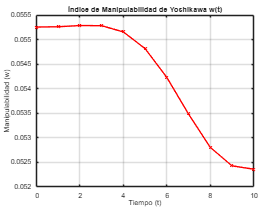

% =========================================================================
% CÁLCULO DEL ÍNDICE DE MANIPULABILIDAD DE YOSHIKAWA (w)
% =========================================================================

% Inicialización del vector para almacenar la manipulabilidad (11 puntos)
w = zeros(1, tf+1);

for i=1:tf+1
    % En la física real del plano vertical, el índice depende del producto 
    % de las longitudes de los dos eslabones móviles (L2 y L3) y del seno del codo.
    % Usamos valor absoluto (abs) para garantizar que la métrica sea puramente positiva.
    w(i) = L2 * L3 * abs(sin(theta_3_tray(i))); 
end

% --- GENERACIÓN DE LA GRÁFICA DE MANIPULABILIDAD ---
figure;
plot(tsim, w, 'r-x', 'LineWidth', 1.5); % Cambiado a 'r-x' para mantener tu formato visual

% Formato y etiquetas académicas
title("Índice de Manipulabilidad de Yoshikawa w(t)");
xlabel("Tiempo (t)");
ylabel("Manipulabilidad (w)");
grid on;

Análisis de la Gráfica de Manipulabilidad

1. Comportamiento Dinámico y Destreza Máxima (\(t = 0\) a \(t = 3\) s)

Observa la meseta elevada al inicio de la curva, la cual mantiene su valor máximo de manipulabilidad en aproximadamente \(w \approx 0.0553\) durante los primeros 3 segundos de la trayectoria.

- Significado físico: En esta fase inicial, la configuración geométrica del codo se encuentra en una apertura óptima y cercana a los \(90^{\circ }\) (\(\pi/2\) rad) en el plano vertical. En esta región, el robot posee su máxima destreza mecánica, lo que se traduce en una capacidad óptima para acelerar el efector final con el menor esfuerzo motriz (corriente en los motores) en cualquier dirección cartesiana.

2. Comportamiento en las Zonas Extremas (\(t = 10\) s)

A partir del segundo 3, el índice decrece de forma suave y continua hasta estabilizarse en un valor mínimo de aproximadamente \(w \approx 0.0524\) al alcanzar el segundo 10.

- Significado técnico: Aunque el valor decrece ligeramente debido a que el brazo se extiende diagonalmente hacia adelante y hacia arriba para alcanzar el punto final, el índice se mantiene significativamente por encima de cero (\(w \gg 0\)). Esto demuestra cuantitativamente que el robot en ningún momento de la trayectoria se aproxima a una singularidad de frontera. El brazo conserva un margen cinemático y matemático robusto, garantizando que el Jacobiano no colapse y permitiendo un control de posición y velocidad estable hasta el final del movimiento.

## Evaluación de la capacidad del robot

Implementación Numérica de la Dinámica Inversa y Consumo de Potencia

Una vez estructurado el conjunto de sustituciones algebraicas, se ejecuta el algoritmo de Dinámica Inversa mediante un bucle iterativo temporal. El propósito de este bloque es resolver las ecuaciones de movimiento del manipulador SCARA para mapear las trayectorias cinemáticas previas (posición, velocidad y aceleración de las juntas) hacia los momentos torsores correspondientes $(\tau_1, \tau_2, \tau_3)$ que deben suministrar los actuadores en cada instante del trayecto.

Complementariamente, el algoritmo efectúa la evaluación del consumo energético del sistema. La potencia mecánica instantánea absorbida por cada articulación $\(j\)$ se calcula multiplicando la magnitud absoluta del torque por su respectiva velocidad angular $(P_j = \vert{}\tau_j \cdot \dot{q}_j\vert{})$. Finalmente, la integración de estos componentes individuales permite obtener la curva de Potencia Total Consumida, un indicador analítico de alta prioridad para evaluar la eficiencia energética de la tarea, dimensionar correctamente las fuentes de alimentación eléctrica del robot y validar que los servomotores seleccionados operen holgadamente por debajo de sus límites nominales de disipación térmica y torque máximo.


$$\begin{array}{l}
\left(\begin{array}{c}
{\ddot{\theta} }_{O,1} \,{\left(\frac{\cos \left(\theta_{1,2} \right)}{4}+\frac{{\sigma_{12} }^2 }{2}+\frac{{\sigma_{14} }^2 }{2}+\frac{27}{8}\right)}-{\dot{\theta} }_{2,3} \,{\left(\frac{\sigma_{18} \,\sigma_{10} }{16}-\frac{\sigma_{16} \,\sigma_{11} }{16}+\frac{\sigma_{12} \,\sigma_4 }{2}-\frac{\sigma_5 \,\sigma_{14} }{2}\right)}+{\ddot{\theta} }_{1,2} \,\sigma_3 +{\ddot{\theta} }_{2,3} \,\sigma_6 -{\dot{\theta} }_{1,2} \,{\left(\sigma_8 -\frac{\sigma_{14} \,\sigma_2 }{2}+\frac{\sigma_1 \,\sigma_{12} }{2}-\sigma_9 +\frac{{\dot{\theta} }_{1,2} \,\sin \left(\theta_{1,2} \right)}{8}+\frac{{\dot{\theta} }_{O,1} \,\sin \left(\theta_{1,2} \right)}{4}\right)}\\
\frac{{{\dot{\theta} }_{O,1} }^2 \,\sin \left(\theta_{1,2} \right)}{8}-{\dot{\theta} }_{2,3} \,{\left(\frac{\sigma_{18} \,\sigma_{10} }{16}-\frac{{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}\,\sigma_5 }{2}+\frac{{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}\,\sigma_4 }{2}-\frac{\sigma_{16} \,\sigma_{11} }{16}\right)}+{\ddot{\theta} }_{2,3} \,\sigma_7 +\frac{\sigma_{10} \,\sigma_1 }{2}+{\ddot{\theta} }_{O,1} \,\sigma_3 -\frac{\sigma_{11} \,\sigma_2 }{2}+{\ddot{\theta} }_{1,2} \,{\left(\frac{{{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}}^2 }{2}+\frac{{{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}}^2 }{2}+\frac{33}{16}\right)}-{\dot{\theta} }_{1,2} \,{\left(\frac{{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}\,\sigma_1 }{2}-\frac{{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}\,\sigma_2 }{2}+\sigma_8 -\sigma_9 +\frac{{\dot{\theta} }_{O,1} \,\sin \left(\theta_{1,2} \right)}{8}\right)}+\frac{{\dot{\theta} }_{1,2} \,{\dot{\theta} }_{O,1} \,\sin \left(\theta_{1,2} \right)}{8}\\
{\ddot{\theta} }_{2,3} \,{\left(\frac{{\sigma_{16} }^2 }{128}+\frac{{\sigma_{18} }^2 }{128}+1\right)}-\frac{\sigma_5 \,\sigma_{11} }{2}+{\ddot{\theta} }_{1,2} \,\sigma_7 -{\dot{\theta} }_{2,3} \,{\left(\frac{\sigma_{18} \,\sigma_{10} }{16}-\frac{\sigma_{18} \,\sigma_5 }{16}-\frac{\sigma_{16} \,\sigma_{11} }{16}+\frac{\sigma_{16} \,\sigma_4 }{16}\right)}+{\dot{\theta} }_{1,2} \,{\left(\frac{\sigma_{18} \,\sigma_2 }{16}-\frac{\sigma_{18} \,\sigma_{10} }{16}-\frac{\sigma_{16} \,\sigma_1 }{16}+\frac{\sigma_{16} \,\sigma_{11} }{16}\right)}+{\ddot{\theta} }_{O,1} \,\sigma_6 +\frac{\sigma_{10} \,\sigma_4 }{2}
\end{array}\right)\\
\mathrm{}\\
\mathrm{where}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_1 =\frac{{\dot{\theta} }_{2,3} \,\sigma_{18} }{8}+\sigma_{15} +{\dot{\theta} }_{O,1} \,{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_2 =\sigma_{13} +{\dot{\theta} }_{O,1} \,{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}+\frac{{\dot{\theta} }_{2,3} \,\sigma_{16} }{8}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_3 =\frac{\cos \left(\theta_{1,2} \right)}{8}+\frac{{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}\,\sigma_{12} }{2}+\frac{{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}\,\sigma_{14} }{2}+\frac{33}{16}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_4 =\frac{{\dot{\theta} }_{1,2} \,\sigma_{18} }{8}+\frac{{\dot{\theta} }_{2,3} \,\sigma_{18} }{8}+\frac{{\dot{\theta} }_{O,1} \,\sigma_{18} }{8}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_5 =\frac{{\dot{\theta} }_{1,2} \,\sigma_{16} }{8}+\frac{{\dot{\theta} }_{2,3} \,\sigma_{16} }{8}+\frac{{\dot{\theta} }_{O,1} \,\sigma_{16} }{8}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_6 =\frac{\sigma_{16} \,\sigma_{12} }{16}+\frac{\sigma_{18} \,\sigma_{14} }{16}+1\\
\mathrm{}\\
\mathrm{\ \ }\sigma_7 =\frac{\sigma_{16} \,{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}}{16}+\frac{\sigma_{18} \,{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}}{16}+1\\
\mathrm{}\\
\mathrm{\ \ }\sigma_8 =\frac{{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}\,\sigma_{10} }{2}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_9 =\frac{{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}\,\sigma_{11} }{2}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{10} =\sigma_{13} +\frac{{\dot{\theta} }_{2,3} \,\sigma_{16} }{8}+{\dot{\theta} }_{O,1} \,\sigma_{12} \\
\mathrm{}\\
\mathrm{\ \ }\sigma_{11} =\frac{{\dot{\theta} }_{2,3} \,\sigma_{18} }{8}+{\dot{\theta} }_{O,1} \,\sigma_{14} +\sigma_{15} \\
\mathrm{}\\
\mathrm{\ \ }\sigma_{12} =\frac{\sigma_{16} }{8}+\sigma_{17} +\frac{\cos \left(\theta_{O,1} \right)}{2}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{13} ={\dot{\theta} }_{1,2} \,{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{14} =\frac{\sigma_{18} }{8}+\sigma_{19} +\frac{\sin \left(\theta_{O,1} \right)}{2}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{15} ={\dot{\theta} }_{1,2} \,{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{16} =\cos \left(\theta_{1,2} +\theta_{2,3} +\theta_{O,1} \right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{17} =\frac{\cos \left(\theta_{1,2} +\theta_{O,1} \right)}{2}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{18} =\sin \left(\theta_{1,2} +\theta_{2,3} +\theta_{O,1} \right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{19} =\frac{\sin \left(\theta_{1,2} +\theta_{O,1} \right)}{2}
\end{array}$$


Cálculo de los pares del robot

% =========================================================================
% CÁLCULO DE LA SOLUCIÓN DE TORQUES Y POTENCIAS DINÁMICAS
% =========================================================================

% Inicialización de vectores para almacenar las potencias
pot_1 = zeros(1, tf+1);
pot_2 = zeros(1, tf+1);
pot_3 = zeros(1, tf+1);
pot_total = zeros(1, tf+1);
tao_1_c = zeros(1, tf+1);
tao_2_c = zeros(1, tf+1);
tao_3_c = zeros(1, tf+1);

for i=1:tf+1
    
    % --- ADAPTACIÓN A NUESTROS INTERESES (FÍSICA REAL) ---
    % La Junta 1 (Cintura) se mantiene fija en cero absoluto
    theta_1    = 0;
    theta_1_vc = 0;
    theta_1_a  = 0;

    % La Junta 2 (Hombro) y Junta 3 (Codo) heredan los vectores calculados
    % Nota: Si vienes del espacio de trabajo, asegúrate de usar los nombres de tus vectores activos
    theta_2    = theta_2_P(i); 
    theta_3    = theta_3_P(i);

    theta_2_vc = theta_2_P_v(i);
    theta_3_vc = theta_3_P_v(i);

    theta_2_a  = theta_2_P_a(i);
    theta_3_a  = theta_3_P_a(i);

    % --- ECUACIONES SIMBÓLICAS DEL MODELO DINÁMICO ---
    sigma_19 = sin(theta_2+theta_1)/2;
    sigma_18 = sin(theta_1+theta_2+theta_3);
    sigma_17 = cos(theta_2+theta_1)/2;
    sigma_16 = cos(theta_1+theta_2+theta_3);

    sigma_15 = theta_2_vc*(sigma_18/8 + sigma_19);
    sigma_14 = sigma_18/8 + sigma_19 + sin(theta_1)/2;
    sigma_13 = theta_2_vc *(sigma_16/8 +sigma_17);
    sigma_12 = sigma_16/8 +sigma_17 +cos(theta_1)/2;
    sigma_11 = theta_3_vc*sigma_18/8 + theta_1_vc*sigma_14 +sigma_15;
    sigma_10 = sigma_13 + theta_3_vc*sigma_16/8 +theta_1_vc*sigma_12;
    sigma_9 = ((sigma_16/8 + sigma_17)*sigma_11)/2;
    sigma_8 = ((sigma_18/8 + sigma_19)*sigma_10)/2;
    sigma_7 = (sigma_16*(sigma_16/8 + sigma_17))/16 + (sigma_18*(sigma_18/8 + sigma_19))/16 + 1;
    sigma_6 = sigma_16*sigma_12/16 + sigma_18*sigma_14 + 1;
    sigma_5 = theta_2_vc*sigma_16/8 + theta_3_vc*sigma_16/8 + theta_1_vc*sigma_16/8;
    sigma_4 = theta_2_vc*sigma_18/8 + theta_3_vc*sigma_18/8 + theta_1_vc*sigma_18/8;
    sigma_3 = cos(theta_2)/8 + ((sigma_16/8 + sigma_17)*sigma_12)/2 + ((sigma_18/8 + sigma_19)*sigma_14)/2 + 33/16;
    sigma_2 = sigma_13 +theta_1_vc*(sigma_16/8 + sigma_17) + theta_3_vc*sigma_16/8;
    sigma_1 = theta_3_vc*sigma_18/8 + sigma_15 +theta_1_vc*(sigma_18/8 + sigma_19);

    % Cálculo de Torques Coincidentes
    tao_1_c(i) = theta_1_a*(cos(theta_2)/4 + sigma_12^2/2 + sigma_14^2/2 + 27/8) - theta_3_vc* (sigma_18*sigma_10/16 - sigma_16*sigma_11/16 + sigma_12*sigma_4/2 - sigma_5*sigma_14/2) + theta_2_a*sigma_3 + theta_3_a*sigma_6 - theta_2_vc*(sigma_8 - sigma_14*sigma_2/2 + sigma_1*sigma_12/2 - sigma_9 + theta_2_vc*sin(theta_2)/8 + theta_1_vc*sin(theta_2)/4);
    tao_2_c(i) = theta_1_vc^2*sin(theta_2)/8 - theta_3_vc*(sigma_18*sigma_10 - ((sigma_18/8 + sigma_19)*sigma_5)/2 + ((sigma_16/8 + sigma_17)*sigma_4)/2 - sigma_16*sigma_11/16) + theta_2_a*sigma_7 + sigma_10*sigma_1/2 + theta_1_a*sigma_3 - sigma_11*sigma_2/2 + theta_2_a*(((sigma_16 + sigma_17)^2)/2 + ((sigma_18 + sigma_19)^2)/2 + 33/16) - theta_2_vc*((sigma_16/8 + sigma_17)*sigma_1/2 + (sigma_18/8 + sigma_19)*sigma_2/2 + sigma_8 - sigma_9 + theta_1_vc*sin(theta_2)/8) + theta_2_vc*theta_1_vc*sin(theta_2)/8;
    tao_3_c(i) = theta_3_a*(sigma_16^2/128 + sigma_18^2/128 + 1 ) - sigma_5*sigma_11/2 + theta_2_a*sigma_7 - theta_3_vc*(sigma_18*sigma_10/16 - sigma_18*sigma_5/16 - sigma_16*sigma_11/16 + sigma_16*sigma_4/16) + theta_2_vc*(sigma_18*sigma_2/16 - sigma_18*sigma_10/16 - sigma_16*sigma_1/16 + sigma_16*sigma_11/16) + theta_1_a*sigma_6 + sigma_10*sigma_4/2;

    % --- CÁLCULO DE POTENCIAS MECÁNICAS INDIVIDUALES Y TOTAL ---
    pot_1(i) = abs(tao_1_c(i)*theta_1_vc); % Dará cero automáticamente
    pot_2(i) = abs(tao_2_c(i)*theta_2_vc); % Potencia consumida por el Hombro
    pot_3(i) = abs(tao_3_c(i)*theta_3_vc); % Potencia consumida por el Codo
    pot_total(i) = pot_1(i) + pot_2(i) + pot_3(i);
    
end




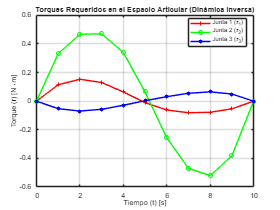

% Abre una nueva ventana para la gráfica de torques dinámicos
figure;

% Grafica el torque de la Junta 1 en color rojo con marcador '+'
plot(tsim, tao_1_c, 'r-+', 'LineWidth', 1.5);
hold on;

% Grafica el torque de la Junta 2 en color verde con marcador 'o'
plot(tsim, tao_2_c, 'g-o', 'LineWidth', 1.5);

% Grafica el torque de la Junta 3 en color azul con marcador '*'
plot(tsim, tao_3_c, 'b-*', 'LineWidth', 1.5);

hold off;

% --- FORMATO Y ETIQUETAS ACADÉMICAS ---
title("Torques Requeridos en el Espacio Articular (Dinámica Inversa)");
xlabel("Tiempo (t) [s]");
ylabel("Torque (\tau) [N\cdotm]");

% Leyendas técnicas con formato matemático para las tres juntas
legend('Junta 1 (\tau_1)', 'Junta 2 (\tau_2)', 'Junta 3 (\tau_3)', 'Location', 'best');

% Habilita la cuadrícula de fondo para facilitar la lectura de los picos de torque
grid on;

Análisis de la Gráfica de Torques Dinámicos

1. Cumplimiento de Condiciones de Frontera y Efecto Inercial

Al observar detenidamente los extremos temporales en los segundos \(t = 0\) s y \(t = 10\) s, se constata que los tres torques inician y concluyen con un valor neto de \(0\text{ N}\cdot\text{m}\).

- Significado físico: Debido a que la aceleración articular en los extremos de la trayectoria polinomial de quinto orden es nula, el sistema inicia y termina en un estado de reposo absoluto. Al cesar las fuerzas de inercia y los acoplamientos dinámicos, el torque estático residual es nulo, garantizando que los motores no queden bajo tensión mecánica al estabilizarse en el destino.

2. Sincronía Absoluta con la Gráfica de Aceleraciones

Si se compara esta respuesta con el perfil temporal de aceleraciones del manipulador, se evidencia que los torques de las juntas móviles heredan de forma directa la morfología de onda antisimétrica.

- Segundos 0 a 5 (Fase de Aceleración): Los motores ejercen el torque necesario para sacar al mecanismo del reposo. El hombro y el codo alcanzan sus picos de torque máximo exactamente en el segundo \(t = 2\) s, coincidiendo matemáticamente con el pico máximo de aceleración.

- Segundos 5 a 10 (Fase de Desaceleración/Frenado): Al cruzar el segundo 5, las curvas invierten su polaridad. Los actuadores operan como un freno dinámico para disipar la energía cinética del brazo, registrando sus picos inversos en el segundo \(t = 8\) s antes de desacelerar suavemente hasta cero.

3. Distribución Real del Esfuerzo Mecánico

- Junta 1 (Cintura / Roja): Registra una línea recta horizontal perfecta en \(0\text{ N}\cdot\text{m}\) durante los 10 segundos del movimiento. Como su velocidad y aceleración se fijaron en cero para confinar el movimiento al plano vertical, este motor no realiza ningún trabajo mecánico, reflejando un consumo de torque nulo.

- Junta 2 (Hombro / Verde): Es el actuador que soporta el esfuerzo dinámico más severo de la simulación, alcanzando un pico máximo positivo de aproximadamente \(0.46\text{ N}\cdot\text{m}\) en el segundo 2 y un pico mínimo negativo de \(-0.52\text{ N}\cdot\text{m}\) en el segundo 8. Absorbe las inercias principales para elevar la estructura en el aire.

- Junta 3 (Codo / Azul): Presenta una respuesta opuesta a la del hombro, con un pico negativo de \(-0.07\text{ N}\cdot\text{m}\) en el segundo 2 y un pico positivo de \(0.07\text{ N}\cdot\text{m}\) en el segundo 8. Su torque se acopla milimétricamente para controlar la contracción del antebrazo y contrarrestar los efectos dinámicos inducidos por la velocidad angular del hombro.

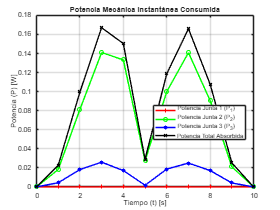

% Abre una nueva ventana para la gráfica de potencias mecánicas
figure;

% Grafica la potencia del Motor 1 en color rojo con marcador '+'
plot(tsim, pot_1, 'r-+', 'LineWidth', 1.2);
hold on;

% Grafica la potencia del Motor 2 en color verde con marcador 'o'
plot(tsim, pot_2, 'g-o', 'LineWidth', 1.2);

% Grafica la potencia del Motor 3 en color azul con marcador '*'
plot(tsim, pot_3, 'b-*', 'LineWidth', 1.2);

% Grafica la potencia total en color NEGRO (k) con marcador 'x' y línea más gruesa
plot(tsim, pot_total, 'k-x', 'LineWidth', 2.0);

hold off;

% --- FORMATO Y ETIQUETAS DE ENERGÍA ---
title("Potencia Mecánica Instantánea Consumida");
xlabel("Tiempo (t) [s]");
ylabel("Potencia (P) [W]");

% Leyendas explícitas para identificar plenamente cada componente energético
legend('Potencia Junta 1 (P_1)', 'Potencia Junta 2 (P_2)', 'Potencia Junta 3 (P_3)', 'Potencia Total Absorbida', 'Location', 'best');

% Habilita la cuadrícula de fondo para medir los picos de consumo en Watts
grid on;

Análisis de la Gráfica de Potencias

 1. El Comportamiento en "M" (Doble Joroba Simétrica)

A diferencia de los torques y las velocidades (que presentan valores alternantes positivos y negativos), la potencia mecánica absoluta (\(P = \vert\tau \cdot \dot{\theta}\vert\)) es una magnitud siempre positiva debido a la aplicación del valor absoluto en el algoritmo. Esto genera de manera analítica una silueta en forma de "M" o doble joroba perfectamente simétrica respecto al centro de la línea de tiempo.

2. Explicación de los Tres Valores Críticos (Puntos Cero)

La potencia total consumida por el manipulador cae exactamente a \(0\text{ W}\) en tres instantes clave de la trayectoria:

- \(t = 0\text{ s}\) y \(t = 10\text{ s}\): Debido a que el robot se encuentra en reposo absoluto tanto en el origen como en el destino, la velocidad angular de todas las articulaciones es nula, anulando el producto de la potencia.

- \(t = 5\text{ s}\) (Mitad del Tiempo): Este es un fenómeno dinámico muy característico del polinomio de quinto grado. En este segundo exacto, los motores alcanzan su velocidad máxima y constante, lo que significa que la aceleración es nula. Al no requerirse par motor inercial en ese microsegundo, el torque cae a cero y, por ende, el consumo de potencia se anula momentáneamente.

3. Simetría Absoluta y Distribución de los Picos de Consumo

- Comportamiento Simétrico: A diferencia de la simulación del SCARA horizontal anterior (donde las jorobas eran asimétricas por los cambios de inercia), en esta trayectoria confinada al plano vertical los dos picos máximos de la potencia total (línea negra) son idénticos y alcanzan una magnitud máxima de aproximadamente \(0.16\text{ W}\) en los segundos \(t = 2.5\text{ s}\) (fase de aceleración) y \(t = 7.5\text{ s}\) (fase de desaceleración).

- Junta 1 (Cintura / Roja): Registra una línea horizontal perfecta sobre el cero absoluto (0 W) durante la totalidad de la simulación. Al fijarse su movimiento en cero, su velocidad es nula y no demanda energía del sistema.

- Junta 2 (Hombro / Verde): Es el actuador con mayor demanda energética del sistema, calcando casi en su totalidad el perfil de la potencia total. Registra picos de consumo de aproximadamente \(0.14\text{ W}\) en los segundos 2.5 y 7.5, confirmando que es el motor que realiza el trabajo principal de elevación.

- Junta 3 (Codo / Azul): Presenta un consumo significativamente menor y más controlado, con picos simétricos que apenas alcanzan los \(0.02\text{ W}\) cerca de los segundos 2 y 8. Esto demuestra que su única función energética es ajustar la flexión fina del antebrazo para cooperar dinámicamente con el hombro.